# **Plotting brain signal functions for beginners 1**

This is a MATLAB live script with some useful plotting ideas for beginners in brain signal processing with MATLAB

## Opening the sample file

To start, you can use the sample file saved in the files folder called 'example1.mat'.

load('files/example1.mat');

 This file contains the following variables:

- **fs:** is the sampling frequency of the signals (samples/second)

- **signalOneChannel:** this is 5 seconds of a single channel signal

- **signalMultiChannel:** this is 5 seconds of a multi channel (159 channels) scalp signal (ex. MEG or EEG signal)

- **posMultiChannel: **this is the position (X,Y,Z) of each one of the channels

- **sourceSignals: **this is 5 seconds of a multi channel (177 channels) source signals. Source signals are signals located inside the head. 

- **posSourceSignals: **this is the position (X,Y,Z) of each one of the source signals

- **cortex: **this is the surface triangular mesh of the brain of a subject. It comprises a set of triangles that are connected by their common edges.

- **head: **this is the surface triangular mesh of the head of a subject. It comprises a set of triangles that are connected by their common edges.

## **Creating the time vector**

To plot our signals vs time, we need to create a time vector. We can create this vector if we know the sampling frequency and the length (in samples) of our signals the easyest way to do this is using the linspace function:

time=linspace(0,length(signalOneChannel)/fs,length(signalOneChannel)); 

You can use matlab help to see what this function does:

help linspace

 linspace Linearly spaced vector.
    linspace(X1, X2) generates a row vector of 100 linearly
    equally spaced points between X1 and X2.
 
    linspace(X1, X2, N) generates N points between X1 and X2.
    For N = 1, linspace returns X2.
 
    Class support for inputs X1,X2:
       float: double, single
 
    See also logspace, colon.

    Reference page for linspace
    Other functions named linspace



## Removing the mean of the signal

Sometimes, we will need to remove the mean value of the signal. We can do this using the function 'detrend':

signalOneChannel=detrend(signalOneChannel,'constant'); % Caution! by doing this, we are replacing the signalOneChannel value with the new value

## Plotting one-channel signal

Using the following code we can plot a one-channel signal:

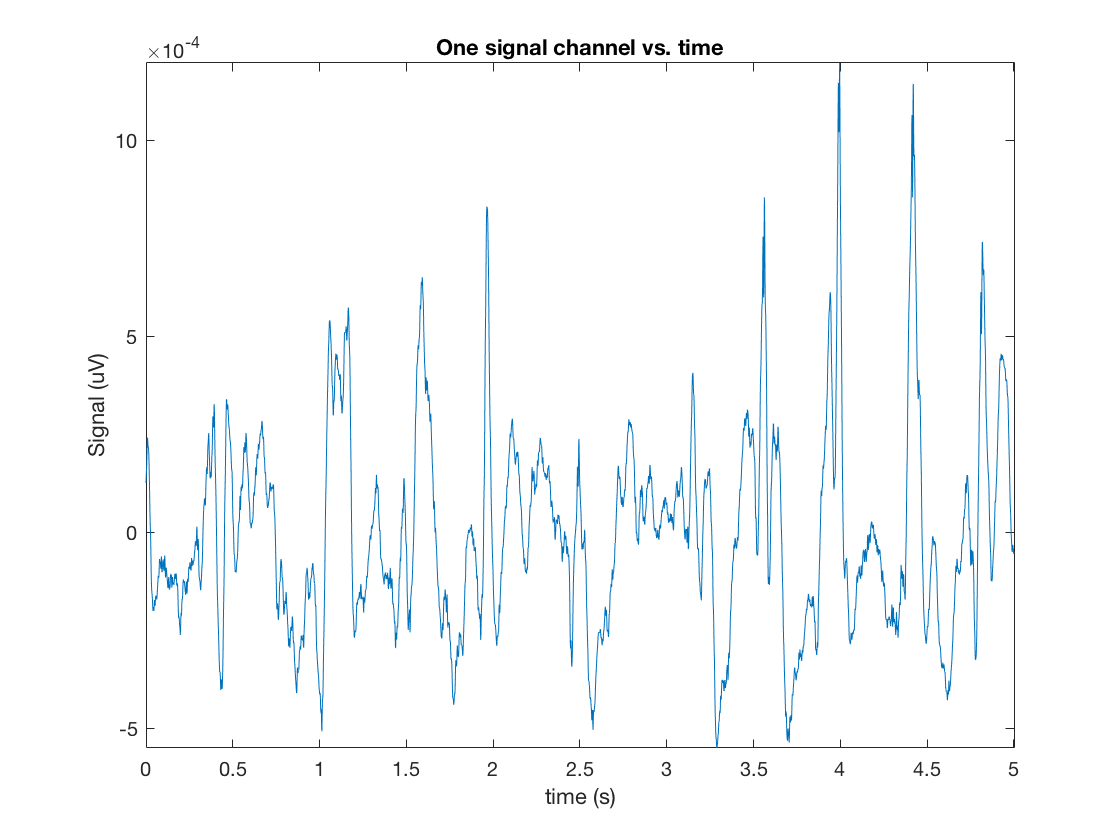

close all % Close all the figures
figure(1); % This creates a a new figure (Figure 1)
plot(time,signalOneChannel) % We use the plot function to plot signal vs time
axis tight % With this, we make our X and Y axis tight to de max-min X and Y values of our function
title('One signal channel vs. time'); % We define a title for our figure
xlabel('time (s)') % the label for X axis
ylabel('Signal (uV)') % the label for Y axis

Imagine that we need to plot the values above a certain threshold (for example, mean(signal)+3*SD(signal). We can plot more information in the same plot:

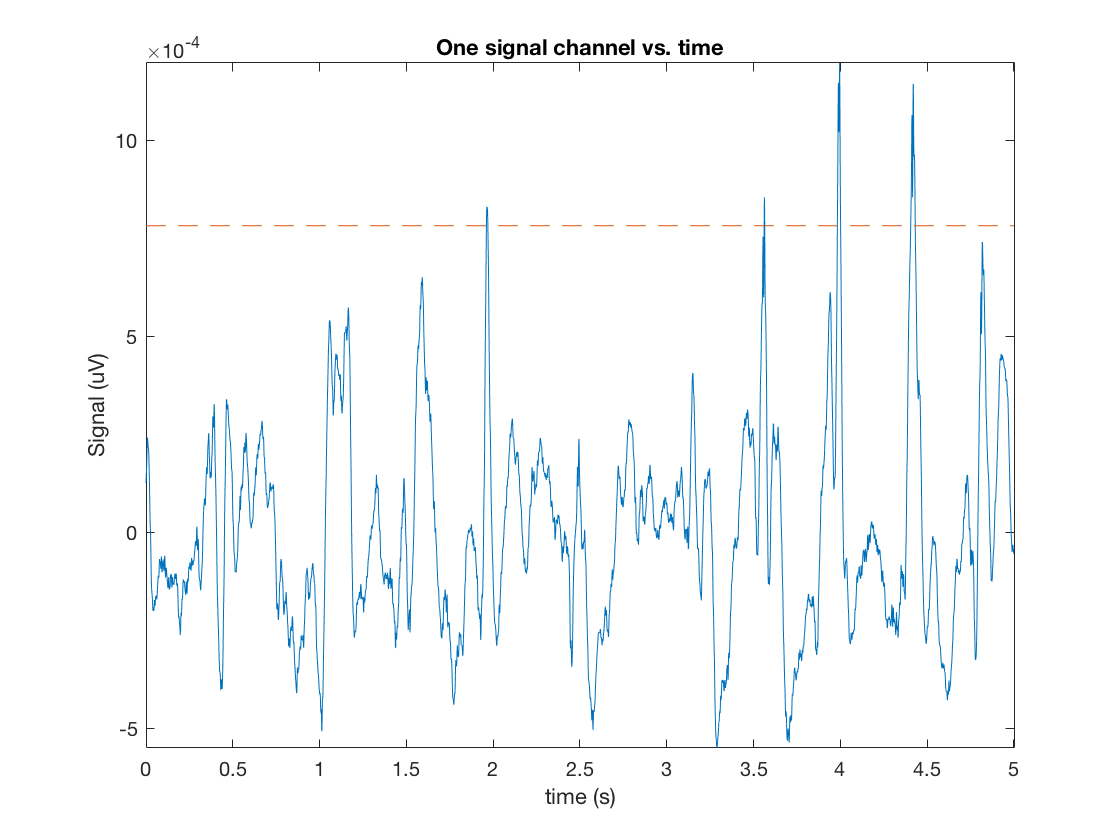

hold on % With this, we hold the current axis and its properties
threshold=mean(signalOneChannel)+3*std(signalOneChannel); % We obtain our threshold.
line([time(1) time(end)],[threshold threshold],'Color',[0.85 0.33 0.1],'LineStyle','--') % Here we can see another way of plotting. Color and Linestyle can be modified

Also, with the following code, we can plot the points that are above this threshold:

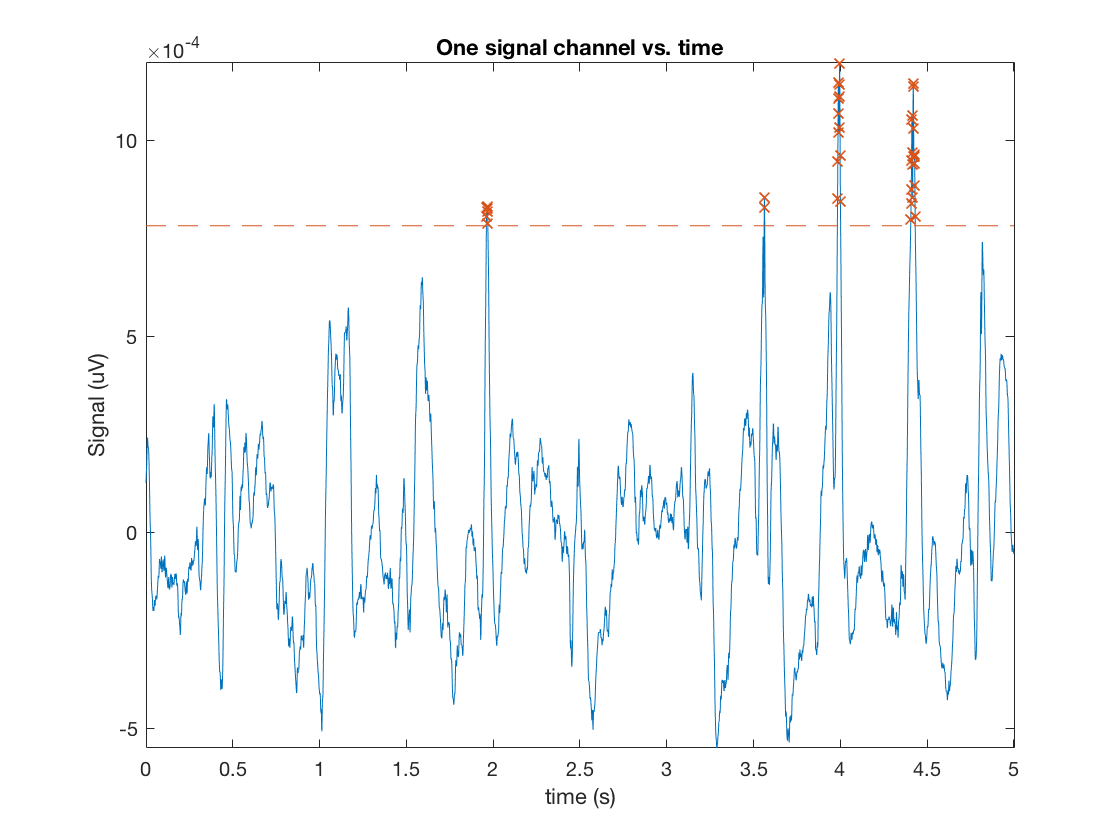

idxThr=find(signalOneChannel>threshold); % Get the indexes higher than threshold
plot(time(idxThr),signalOneChannel(idxThr),'x') % We plot only the indexes that we obained. the 'x' is the marker that we are using. 

## Plotting a multi-channel signal

Sometimes is useful to plot more than one signal together (for example with EEG or MEG recordings, where we have several channels). 

Imagine that we want to plot the first 5 channels from our *signalMultiChannel *variable:

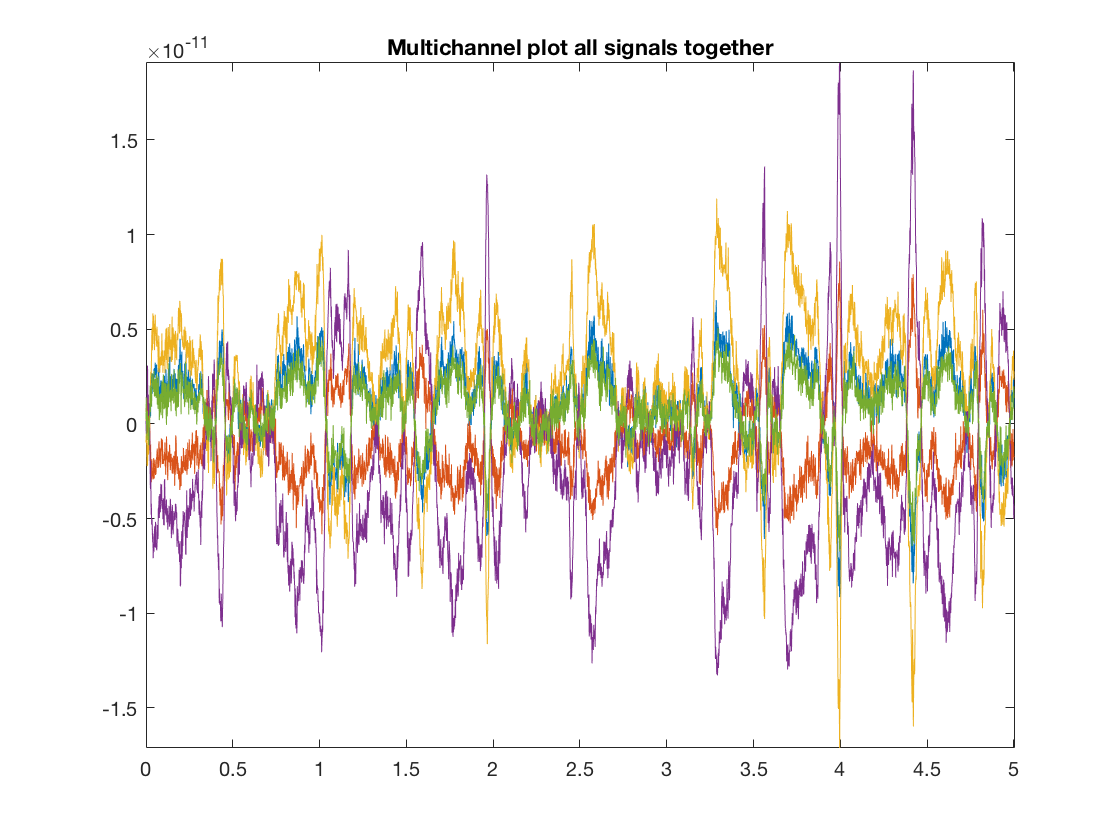

signalMultiChannel=detrend(signalMultiChannel,'constant');
figure(2) % We open a new figure
plot(time,signalMultiChannel(1:5,:)) % Plot from 1 to 10, all the samples
axis tight
title('Multichannel plot all signals together')

We plotted the 10 channels but they are overlapped and it is difficult to see the information of each one of the channels. There are several ways to plot the signals separated.

One of the ways is using the subplot function

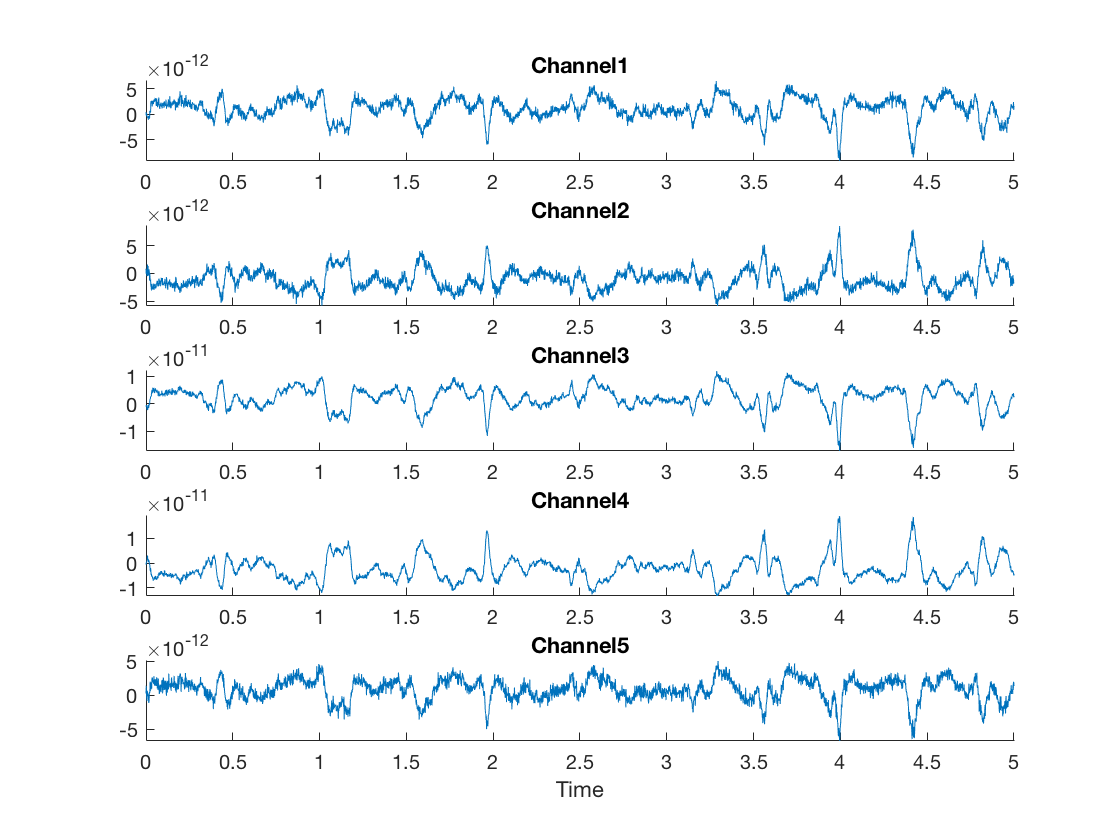

figure(3) % We open a new figure

for i=1:5
    subplot(5,1,i) % We call subplot, we want 5 rows and 1 column plot
    plot(time,signalMultiChannel(i,:)) % we plot the i^th channel
    title(['Channel' num2str(i)]) % With this, we can create a title that change on every iteration
    axis tight 
    box off
end
xlabel('Time')

When we are working with a low number of channels (or anything you are triying to plot), using subplot is useful. However, as the number of channel increase, there are some other ways to plot multi-channel signals. 

One way is to use a single plot and to "move" the signals through that plot. If we want to plot the first 10 signals of the signalMultiChannel variable:

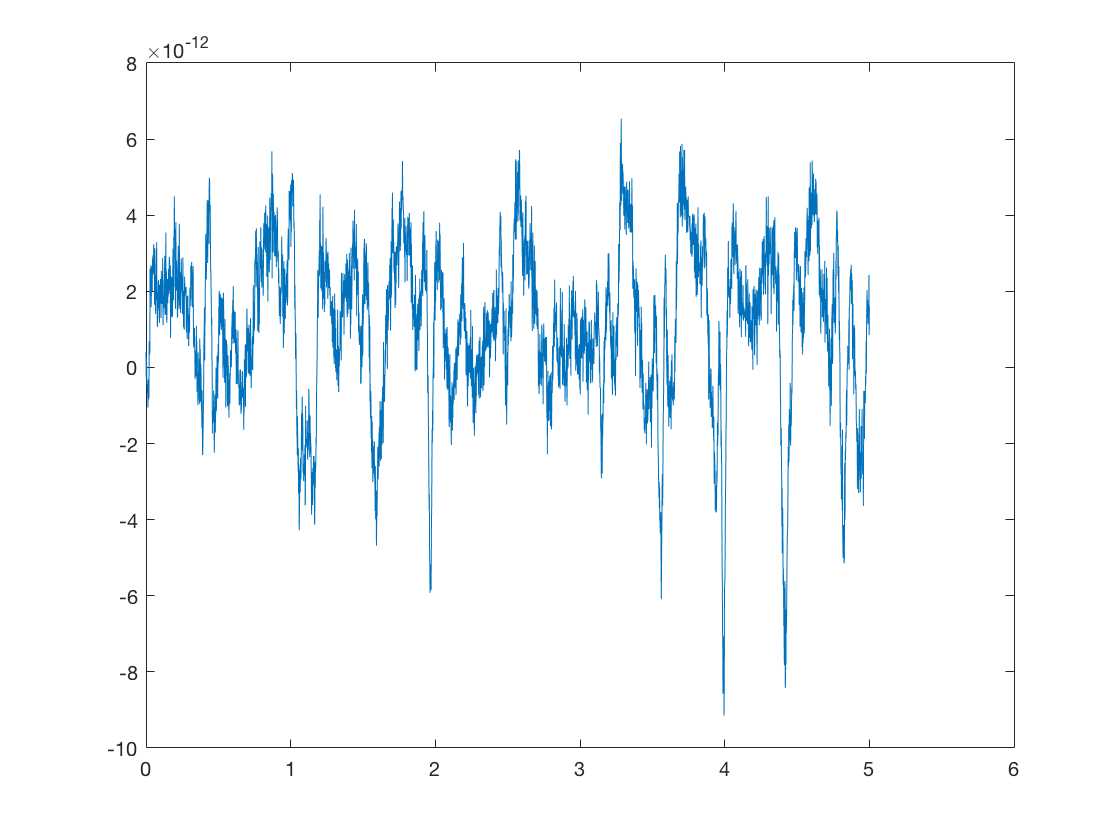

figure(4)

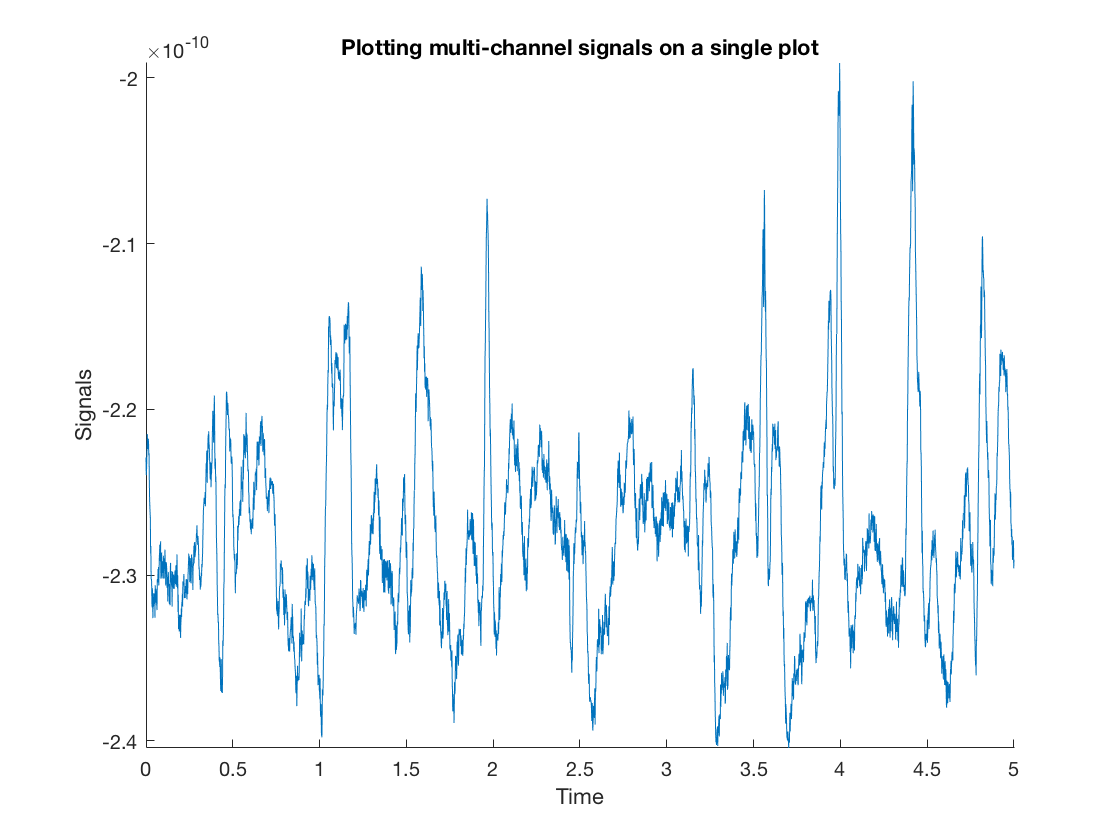

% Multiplying factor
k=max(max(signalMultiChannel(1:10,:)));
for i=1:10
    plot(time, signalMultiChannel(i,:)-(i-1)*k)
    %                         hold on
end
axis tight
box off
xlabel('Time')
ylabel('Signals')
title('Plotting multi-channel signals on a single plot')

here, by using "`(i-1)*k", `move down the signal that we are plotting. K, is a multipliying factor, computed as the maximum value of our signals.

Imagine that we want to add labels to each one of the signals to identify them. This can be done by modifiying the axis properties:

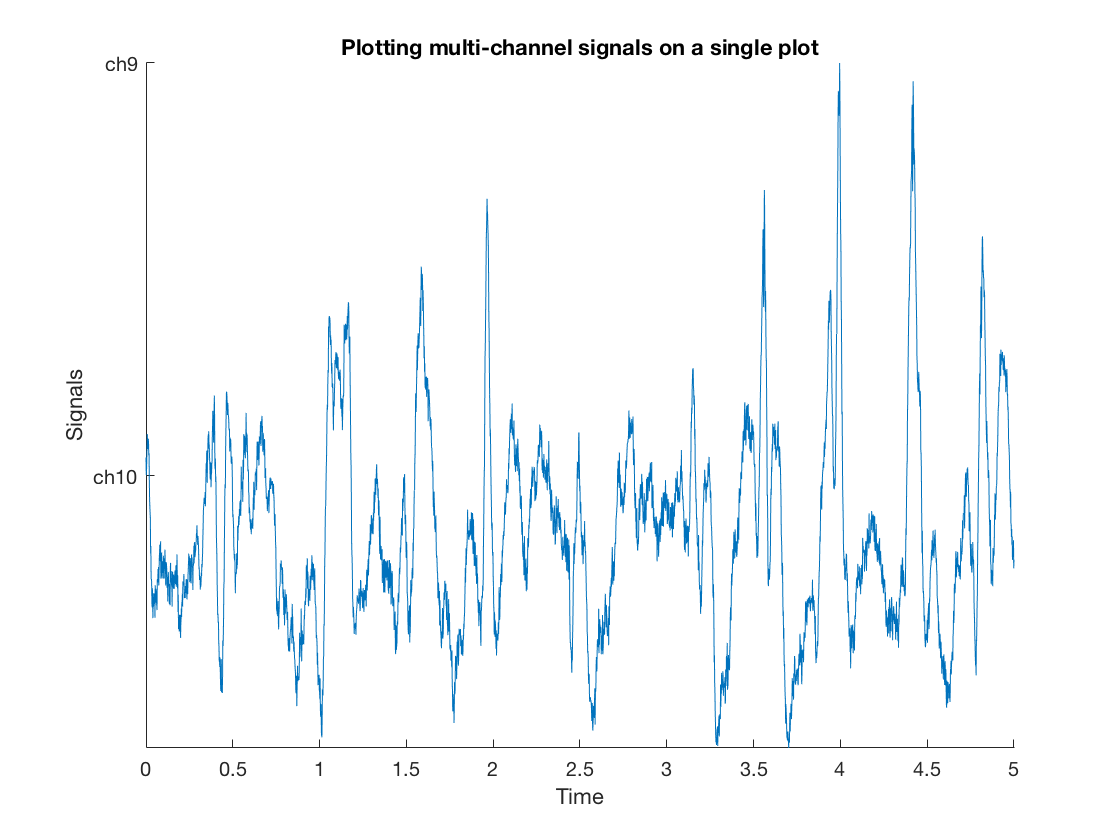

ax=gca; % Obtain current axis handles
% YTick determine the numbers shown in the y axis. With linspace we are programming
% 10 points from -k*(i-1) to 0
ax.YTick=linspace(-k*(i-1),0,10); 

% Now, we will rename this ticks with whatever we want. In this case, imagine that the
% name of the channels is ch1, ch2, ch3, ..., ch10.
for i=1:10
    % num2str converts a number to a string with this, we create a cell array with the 
    % name of channels 
    channels{i}=['ch' num2str(i)];  
end
% With fliplr, we flip the cell array. The lowest tick must correspond to the channel 10 and 
% the highest tick must correspond to channel 1
ax.YTickLabel=fliplr(channels);  

A way to see all the channels activations in a fast way is to use images. For example, if we want to plot all the data matrix we could use:

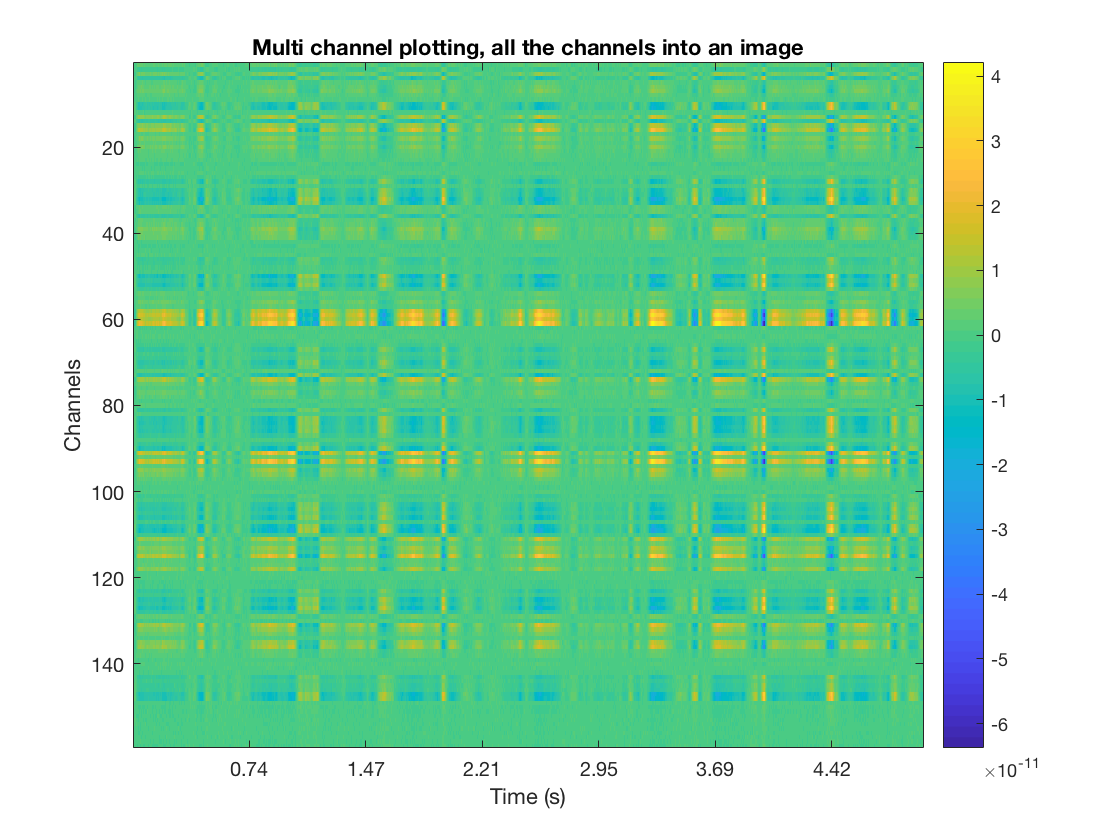

figure(5)
imagesc(signalMultiChannel)
% Here, we have each one of the channels vs the samples (not time), to changle the x-axis to time:
ax=gca; 
ax.XTickLabel=round(100*time(ax.XTick))/100; % Multipliying, rounding and dividing is a way of round to 2 decimals
title('Multi channel plotting, all the channels into an image')
ylabel('Channels')
xlabel('Time (s)')
colorbar % With colorbar, we can see the range of values of our signal. 

We can change the colormap to display the image with a different color scale. Type 'help colormap' to see which type of colormaps are provided. You can also create your own colormaps. 

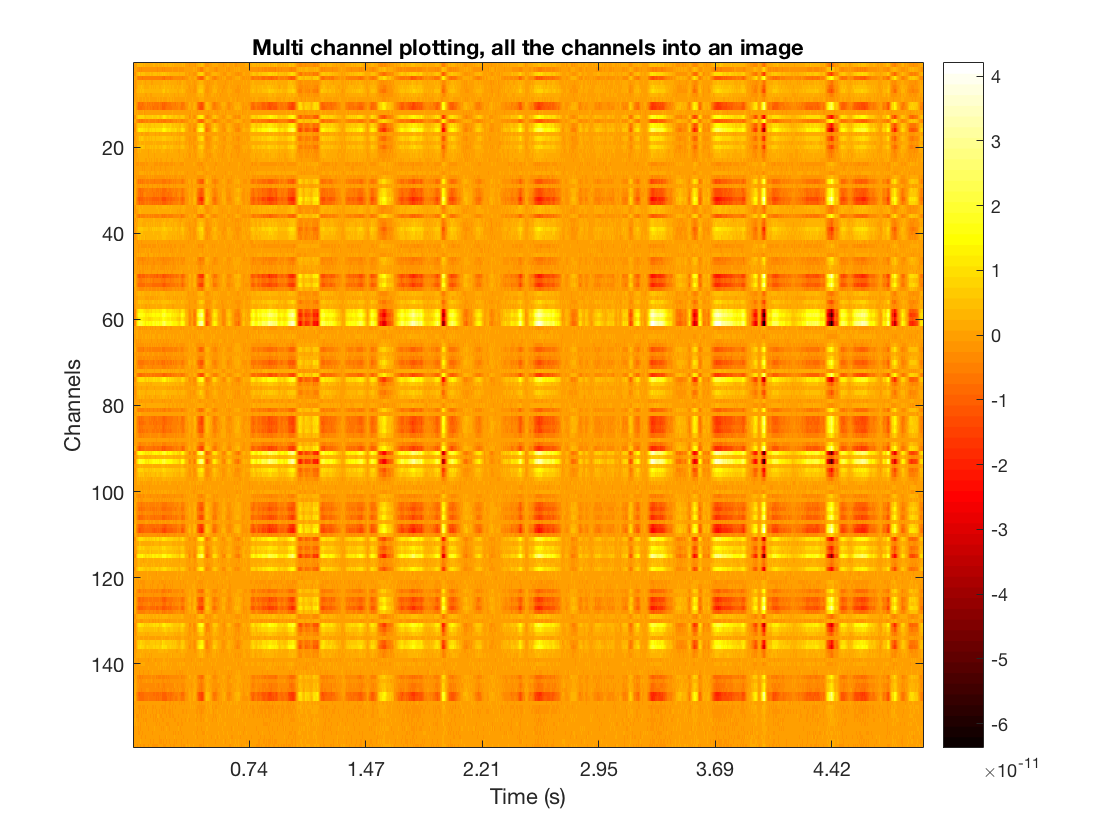

colormap hot

Here we can see all the channels but in this graphic not information about the actual position of the sensors is provided. To plot that information, we could use a topographical distribution. Fieldtrip, brainstorm and EEGlab provide powerful functions to plot a topographical distribution. Here, some simple topographical plots will be explained. 

With the following code, we can plot a 2-D topographical representation of our signals in one timepoint:

*Note: this plot is not visualized properly in the matlab live script, please open it using the "open in new figure" option that appear at the right-top of the screen.*

X=posMultiChannel(:,1); % We save the X coordinates of the position 
Y=posMultiChannel(:,2); % We save the Y coordinates of the position 
Signal=signalMultiChannel(:,1); % We select which signal we want to plot, in this case, we plot the first sample
vq = TriScatteredInterp(X,Y,Signal,'natural'); 

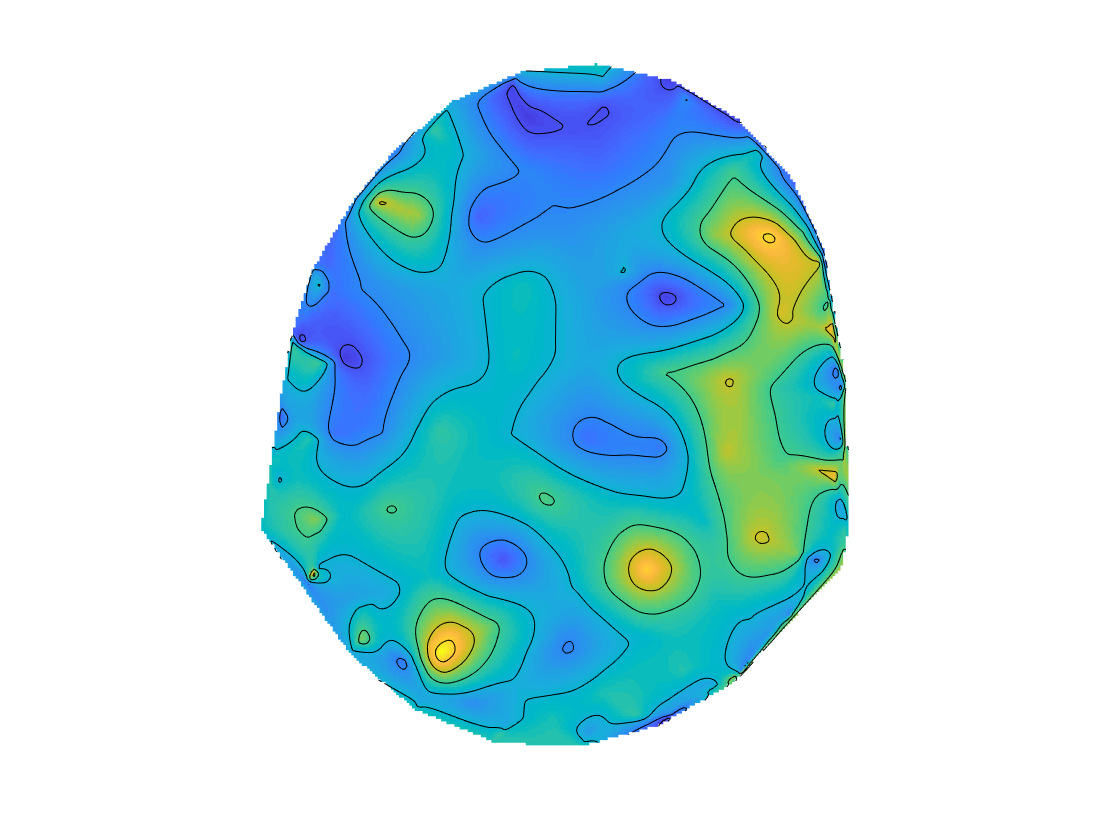

figure(5)
resolution=0.001;
ti = min(min(X),min(Y)):resolution:max(max(X),max(Y));
[qx,qy] = meshgrid(ti,ti);
qz = vq(qx,qy);
surf(qx,qy,qz,'FaceColor','flat','EdgeColor','none');
hold on
contour(qx,qy,qz,'Color',[0 0 0]); % to plot the contour lines in black
view(0,90) % go to X-Y view
ax=gca;
camroll(90) % rotate to see front up. 
colormap parula
axis equal
axis off

With this, for example we can plot the normalized power in a certain frequency band (for example, the alpha band, from 7.5 to 12.5 Hz):

bp=bandpower(signalMultiChannel',fs,[7.5 12.5]);
bpall=bandpower(signalMultiChannel');
figure(6)
vq=TriScatteredInterp(X,Y,(bp./bpall)','natural'); 

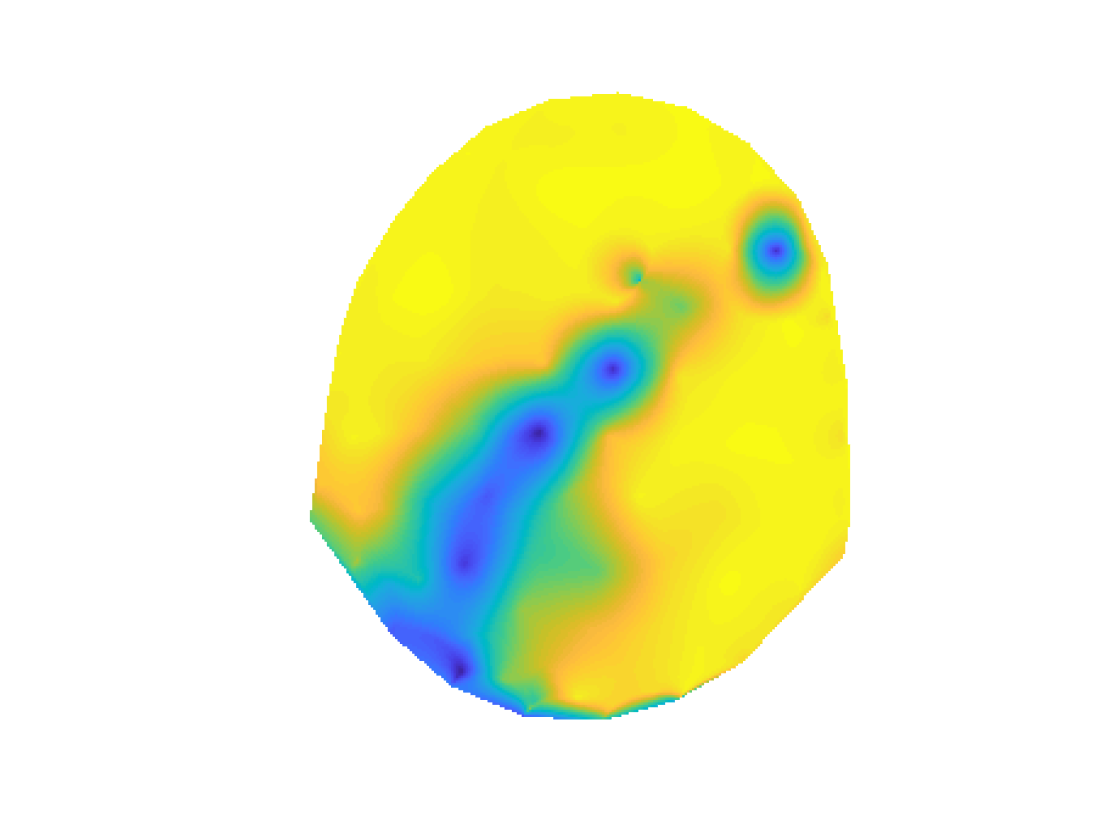

resolution=0.001;
ti = min(min(X),min(Y)):resolution:max(max(X),max(Y));
[qx,qy] = meshgrid(ti,ti);
qz = vq(qx,qy);
surf(qx,qy,qz,'FaceColor','flat','EdgeColor','none');
view(0,90) % go to X-Y view
ax=gca;
camroll(90) % rotate to see front up. 
colormap parula
axis equal
axis off

correl=[];
for i = 1:size(signalMultiChannel,1)
    aux=corrcoef(signalOneChannel,signalMultiChannel(i,:));
    correl(i)=(aux(1,2)); 
end
vq = TriScatteredInterp(X,Y,correl','natural'); 

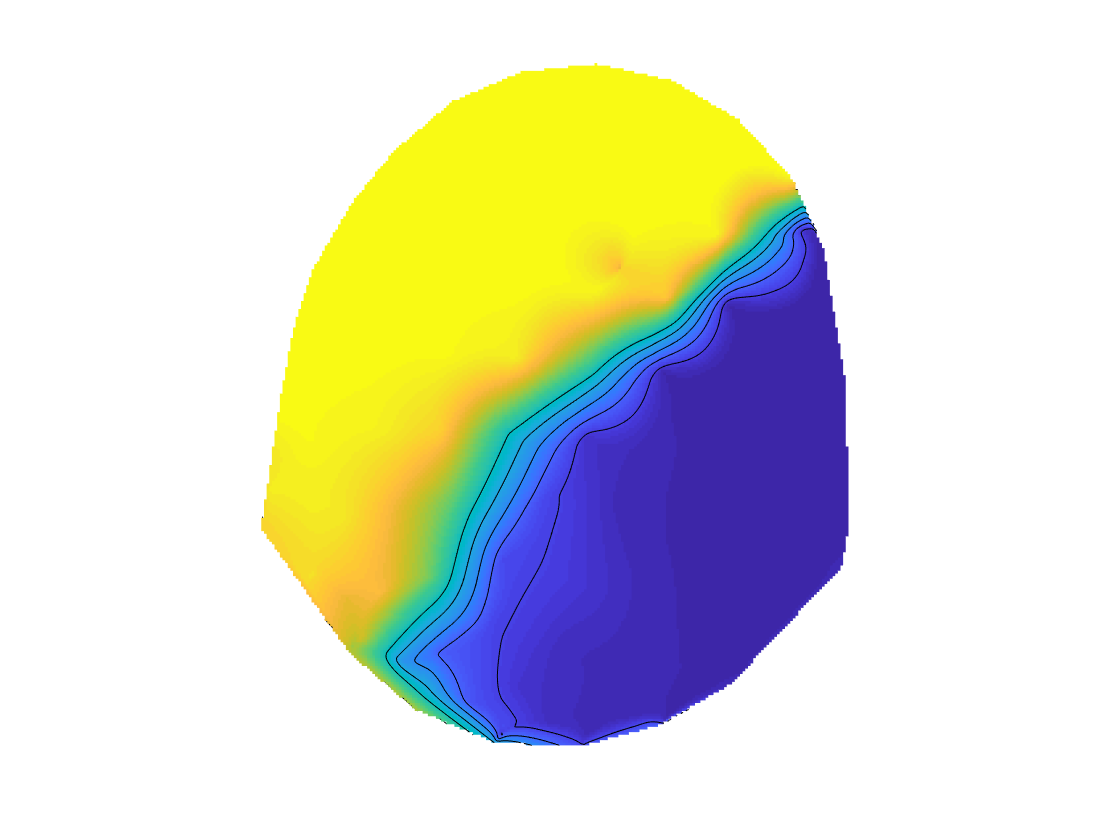

figure(7)
resolution=0.001;
ti = min(min(X),min(Y)):resolution:max(max(X),max(Y));
[qx,qy] = meshgrid(ti,ti);
qz = vq(qx,qy);
surf(qx,qy,qz,'FaceColor','flat','EdgeColor','none');
hold on
contour(qx,qy,qz,'Color',[0 0 0]); % to plot the contour lines in black
view(0,90) % go to X-Y view
ax=gca;
camroll(90) % rotate to see front up. 
colormap parula
axis equal
axis off

## Plotting source data

While is easy to find ways to plot sensor data in fieldtrip or eeglab, source data is more difficult to plot in a meaningful way. Here are some examples to plot this data overlapped with the mesh of the brain or the head of the subject. 

With the following code we can plot the triangular mesh of the subject:

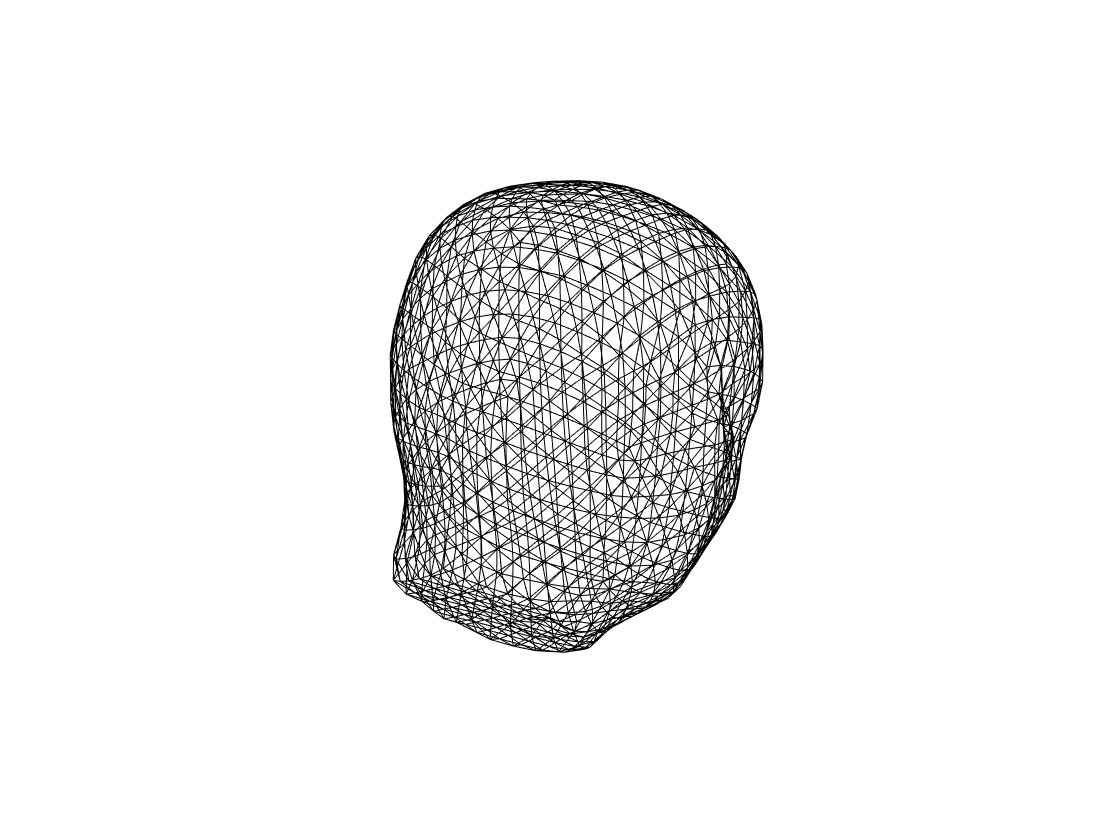

figure(8)
trimesh(head.Faces,head.Vertices(:,1),head.Vertices(:,2),head.Vertices(:,3),'EdgeColor',[0 0 0],'FaceColor','none')
axis equal
axis off

We can also plot the triangular mesh of the brain, overlapped with the head. With the properties of edges and faces, we can change how we visualize the color and alpha (transparency) of the meshes. 

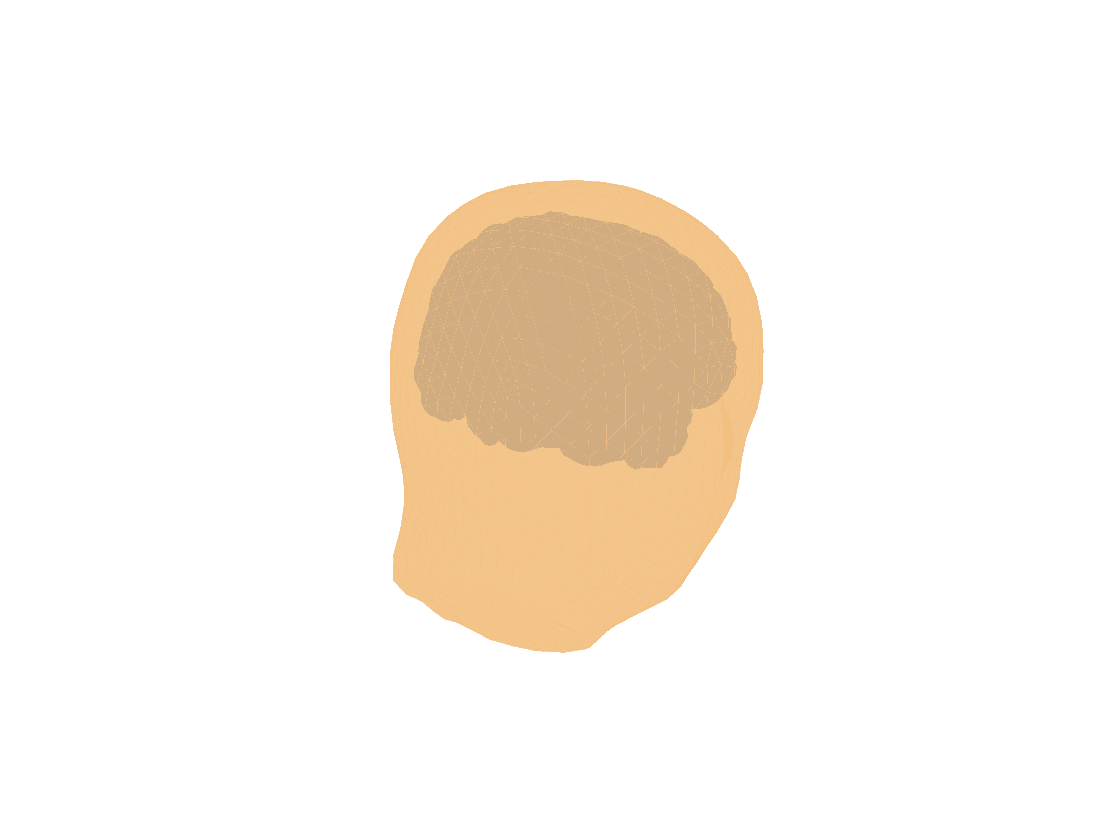

figure(9)
trimesh(head.Faces,head.Vertices(:,1),head.Vertices(:,2),head.Vertices(:,3),'EdgeColor',[0.95 0.75 0.5],'FaceColor',[0.95 0.75 0.5], 'EdgeAlpha',0.7,'FaceAlpha',0.7)
axis equal
axis off
hold on
trimesh(cortex.Faces,cortex.Vertices(:,1),cortex.Vertices(:,2),cortex.Vertices(:,3),'EdgeColor',[0.5 0.5 0.5],'FaceColor',[0.5 0.5 0.5], 'EdgeAlpha',0.9,'FaceAlpha',0.9)

We can plot the source sensors, using scatter3, along with the head mesh

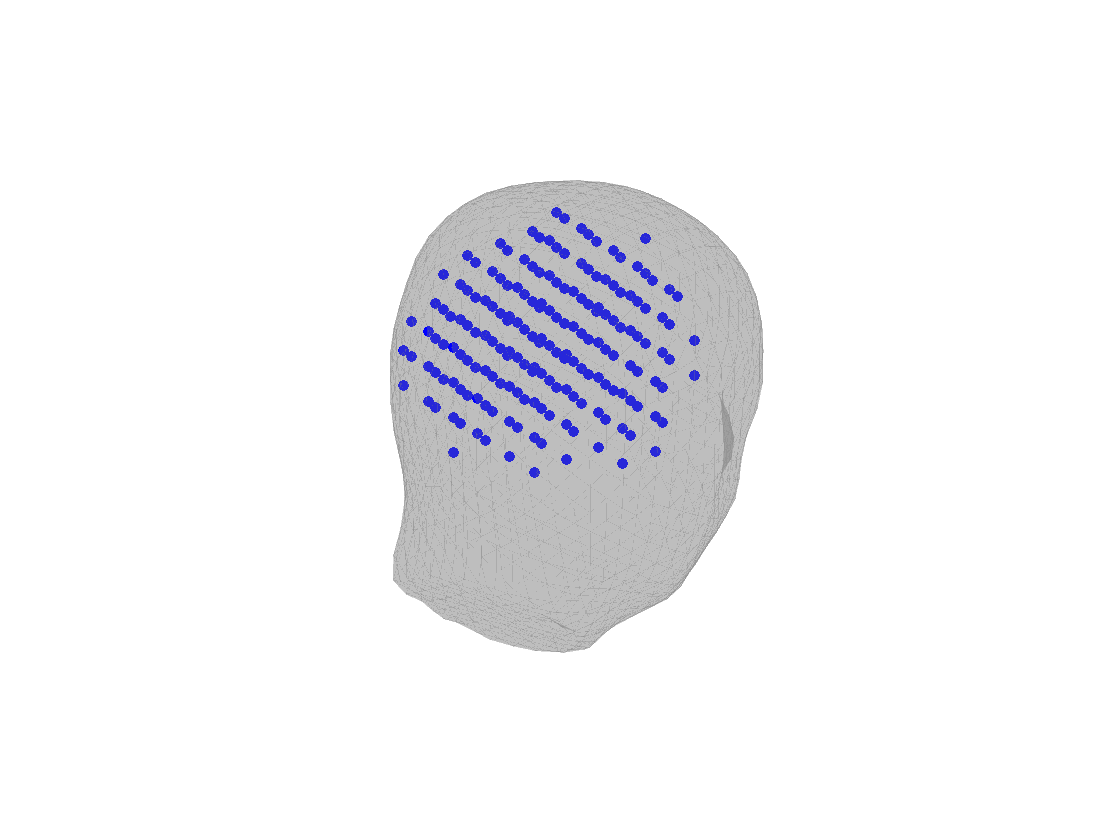

figure(10)
trimesh(head.Faces,head.Vertices(:,1),head.Vertices(:,2),head.Vertices(:,3),'EdgeColor',[0.5 0.5 0.5],'FaceColor',[0.5 0.5 0.5], 'EdgeAlpha',0.3,'FaceAlpha',0.3)
axis equal
axis off
hold on
scatter3(posSourceSignal(:,1),posSourceSignal(:,2),posSourceSignal(:,3),30,'blue','filled')

We can assign a color depending on the value of the source signal, for example, using the colour as the value of the correlation with each of the sensors with the one channel signal

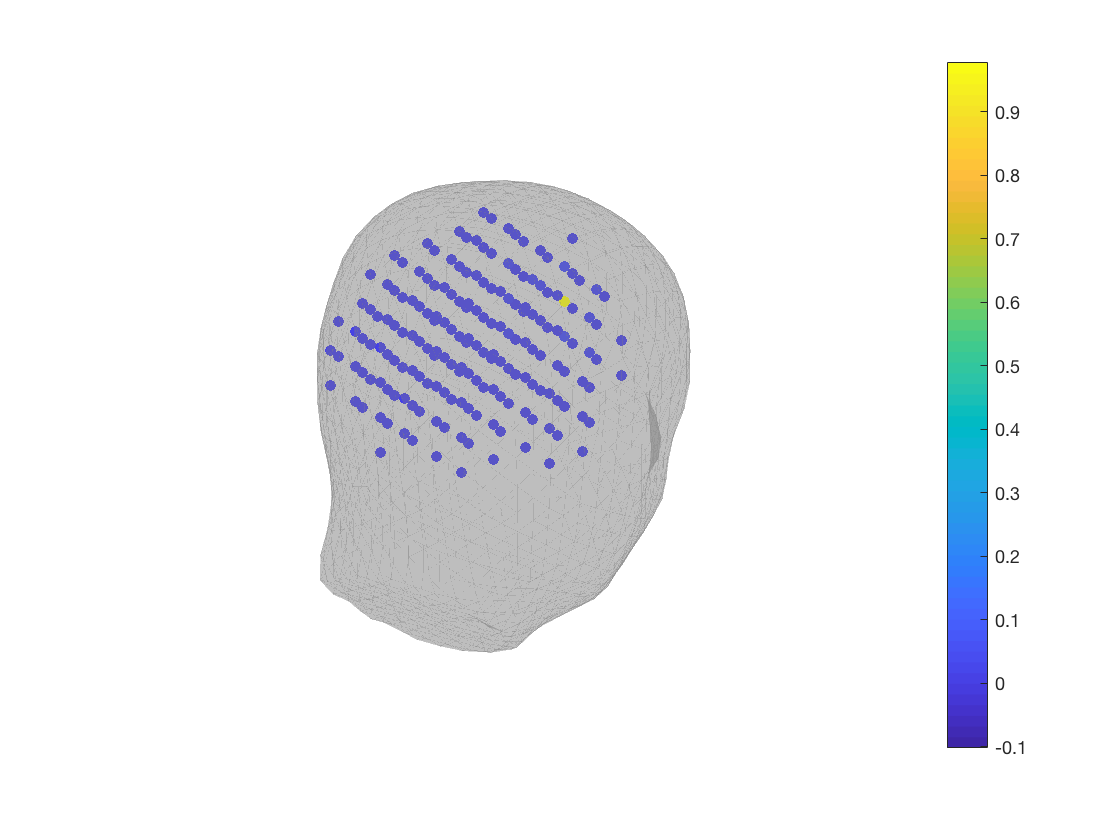

correl=[];
for i = 1:size(sourceSignals,1)
    aux=corrcoef(signalOneChannel,sourceSignals(i,:));
    correl(i)=abs(aux(1,2)); % We don't care if it is a positive or negative correlation
end
figure(11)
trimesh(head.Faces,head.Vertices(:,1),head.Vertices(:,2),head.Vertices(:,3),'EdgeColor',[0.5 0.5 0.5],'FaceColor',[0.5 0.5 0.5], 'EdgeAlpha',0.3,'FaceAlpha',0.3)
axis equal
axis off
hold on
scatter3(posSourceSignal(:,1),posSourceSignal(:,2),posSourceSignal(:,3),30,correl,'filled')
colorbar